## Question Section

In this project, we will consider the question: when do international travel bans need to go into effect in order to reduce the peak infection by 50%?

## Model Section

### Implementation

Each agent has a location.  Depending on parameters and a random number, the agent will "travel" and relocate to another country (unless a travel ban is in effect).  Then, a new connectivity graph is made and the SIR agentic model is run on the graph.

### Baseline Graph

Without a travel ban, this is how the simulation would run, averaged over 20 runs.

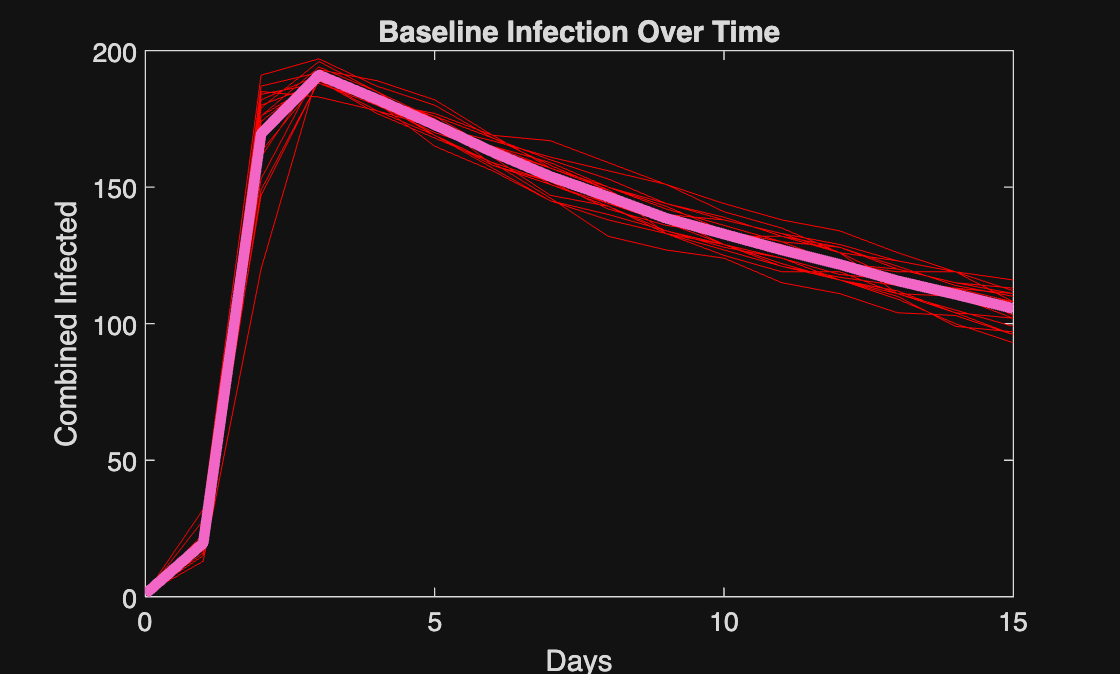

% Parameters
params.N_countries = 5;        % total countries (or 'pods')
params.N_total = 100;          % total agents
params.beta_per_edge = 0.7;    % transmission probability per contact per day
params.gamma = 0.05;           % recovery prob per day
params.p_edge = 0.7;           % prob edge exists in Erdos-Renyi contact graph within country
params.avg_out_travel = 0.7;   % fraction of persons leaving their country per day (row-sum of M)
params.t_max = 15;             % days
params.dt = 1;                 % day step (1)
params.I0_idx = 1;             % initial infected agent id index (or array)
params.n_runs = 20;            % stochastic repeats per ban time for averaging
params.seed_mode = 'fixed';    % 'auto' or 'fixed' (if fixed will use run index to seed)
params.verbose = true;


% Distribute populations: equal by default
Nc = params.N_countries;
params.population = floor(params.N_total / Nc) * ones(Nc,1);
% if remainder, add 1 to first few countries
remn = params.N_total - sum(params.population);
params.population(1:remn) = params.population(1:remn) + 1;

% Build baseline travel matrix M (rows sum to avg_out_travel)
base_rate = params.avg_out_travel;
M = (base_rate/(Nc-1)) * (ones(Nc)-eye(Nc));
params.M = M;

% Ban sweep
ban_search.t_min = 0;
ban_search.t_max = 15;
ban_search.t_step = 1; % daily checks
ban_times = ban_search.t_min:ban_search.t_step:ban_search.t_max;

target_reduction = 50; % percent


% Generate static contact graphs & initial agent assignment
[agents_template, country_agent_ids, G_country] = init_agents_and_graphs(params);

% Baseline (no ban)
[peak_baseline_mean,peak_baseline_std, all_time_series, avg_days] = run_experiments_agent(params, agents_template, country_agent_ids, G_country, Inf);

all_days = zeros(length(avg_days), params.n_runs);
for i = 1:params.n_runs
    all_days(:, i) = all_time_series{i}.I_comb;
end

figure('Name','Baseline Infection Graph');

% Plot individual runs
plot(0:length(avg_days) -1, all_days, 'LineWidth', 0.1, 'LineStyle', '-', 'Color', '#FF0000'); hold on

% Plot baseline time series
plot(0:length(avg_days) -1, avg_days, 'LineWidth', 4);
xlabel('Days'); ylabel('Combined Infected');
title('Baseline Infection Over Time');

%grid on;

### Finding The Right Infection Time

Depending on when a travel ban is activated, how much is the peak infection reduced?


% Sweep ban times
n_b = numel(ban_times);
mean_peaks = zeros(n_b,1);
std_peaks  = zeros(n_b,1);

if params.verbose, disp('Sweeping ban times...'); end

Sweeping ban times...


for k = 1:n_b
    bt = ban_times(k);
    [mu, sigma, ~] = run_experiments_agent(params, agents_template, country_agent_ids, G_country, bt);
    mean_peaks(k) = mu;
    std_peaks(k) = sigma;
    if params.verbose
        fprintf('Ban at %2d d: mean peak = %.3f, std = %.3f\n', bt, mu, sigma);
    end
end

Ban at  0 d: mean peak = 195.000, std = 2.384
Ban at  1 d: mean peak = 38.550, std = 9.934
Ban at  2 d: mean peak = 185.300, std = 13.055
Ban at  3 d: mean peak = 191.150, std = 2.852
Ban at  4 d: mean peak = 191.150, std = 2.852
Ban at  5 d: mean peak = 191.150, std = 2.852
Ban at  6 d: mean peak = 191.150, std = 2.852
Ban at  7 d: mean peak = 191.150, std = 2.852
Ban at  8 d: mean peak = 191.150, std = 2.852
Ban at  9 d: mean peak = 191.150, std = 2.852
Ban at 10 d: mean peak = 191.150, std = 2.852
Ban at 11 d: mean peak = 191.150, std = 2.852
Ban at 12 d: mean peak = 191.150, std = 2.852
Ban at 13 d: mean peak = 191.150, std = 2.852
Ban at 14 d: mean peak = 191.150, std = 2.852
Ban at 15 d: mean peak = 191.150, std = 2.852



% compute percent reductions using mean peaks
reductions = 100 * (peak_baseline_mean - mean_peaks) / peak_baseline_mean;

% find earliest ban time achieving target reduction
idx = find(reductions >= target_reduction, 1, 'first');

if isempty(idx)
    fprintf('No ban time in [%d,%d] days reached >= %.1f%% mean peak reduction.\n', ban_search.t_min, ban_search.t_max, target_reduction);
else
    fprintf('Earliest ban day achieving >= %.1f%% mean peak reduction: %d days\n', target_reduction, ban_times(idx));
    fprintf('Mean peak then = %.3f (baseline = %.3f)\n', mean_peaks(idx), peak_baseline_mean);
end

Earliest ban day achieving >= 50.0% mean peak reduction: 1 days


Mean peak then = 38.550 (baseline = 191.150)


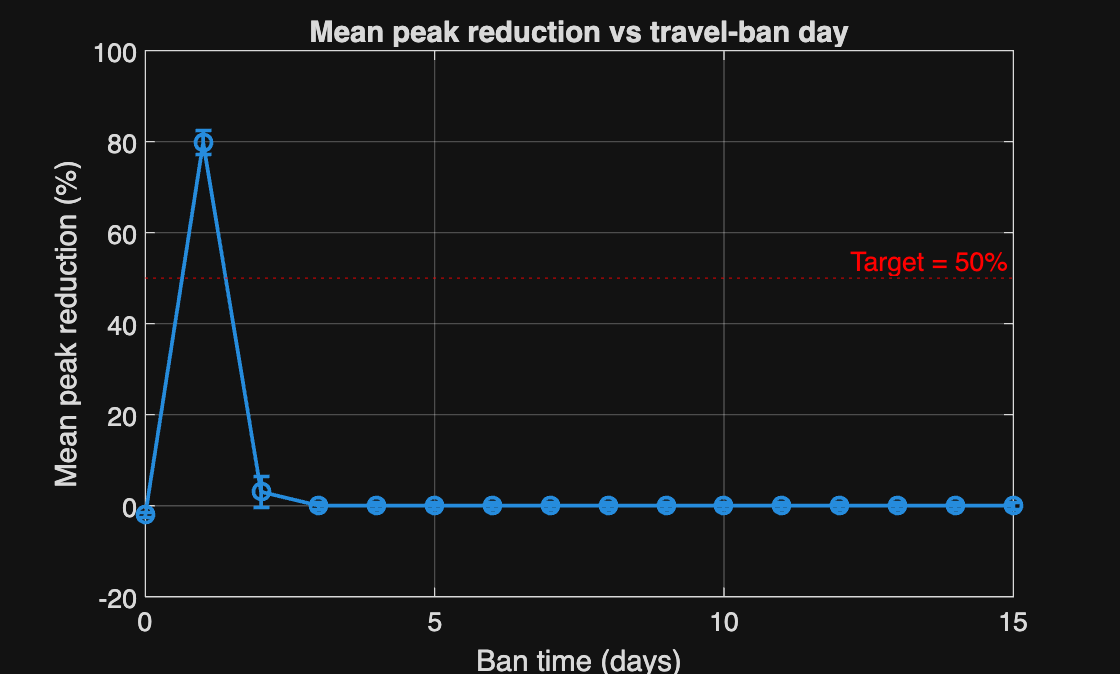


% Plot results: reduction vs ban time and baseline vs best
figure('Name','Peak reduction vs Ban time');
errorbar(ban_times, reductions, 0.5*std_peaks./peak_baseline_mean*100, '-o','LineWidth',1.4);
xlabel('Ban time (days)'); ylabel('Mean peak reduction (%)');
yline(target_reduction, ':r', sprintf('Target = %.0f%%', target_reduction));
title('Mean peak reduction vs travel-ban day');
grid on;

### Result

From our graph above, we can see that, in order to decrease peak infection by 50%, a travel ban must go into effect at **1 day**.  

Here is the graph of the resulting simulation, averaged over 20 runs.

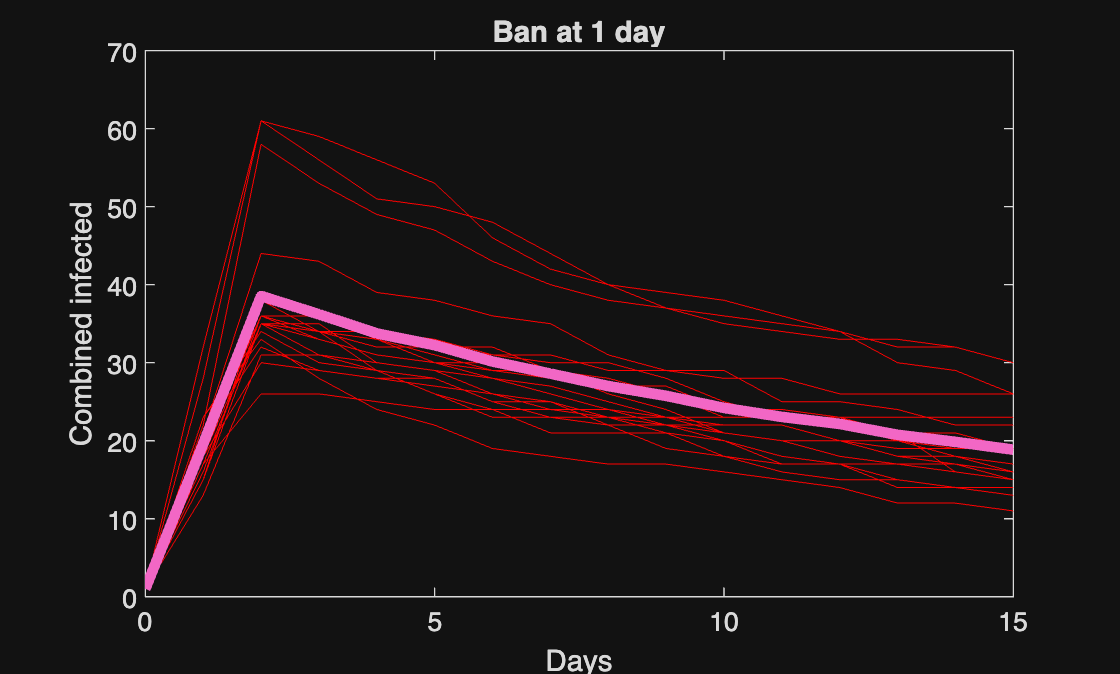

if ~isempty(idx)
    best_bt = ban_times(idx);
    
    [~, ~, all_ts, avg_days] = run_experiments_agent(params, agents_template, country_agent_ids, G_country, best_bt);

    all_days = zeros(length(avg_days), params.n_runs);
    for i = 1:params.n_runs
        all_days(:, i) = all_ts{i}.I_comb;
    end

    figure('Name','Combined infected (example runs)');

    % Plot individual runs
        plot(0:length(avg_days) -1, all_days, 'LineWidth', 0.1, 'LineStyle', '-', 'Color', '#FF0000'); hold on

    plot(0:length(avg_days) - 1, avg_days,'LineWidth',4); 
    xlabel('Days'); ylabel('Combined infected');
    
    title(sprintf('Ban at %d day', best_bt));
    %grid on;
end

We can see that the peak of the new graph works out to be under 50% of the original infection peak.

### Conceptual Validation

The effectiveness of travel bans at curbing infection and decreasing infection peak can be seen in the real world.  During the COVID-19 pandemic, South Korea delayed enacting its travel restrictions in comparison to surrounding countries, and ended up with a higher number of cases (NIH).

## Interpretation Section

Our results show that inacting a total travel ban once []% of the population is infected is enough to decrease the peak infection by 50% in an international scenario.  This supports the claim that travel bans are an effective way to curb pandemics.  However, they have to work almost perfectly.  According to the NIH, "Substantial evidence suggests the need of a near complete shutdown of global travel to contain the epidemic modestly" (NIH). It is widely agreed that the COVID-19 pandemic could have been contained and largely prevented weeks after it was discovered with a global 100% travel ban, but such a ban is not feasible.  In conclusion, travel bans can be very effective when they are strictly enforced, as we have shown with our model, but in reality they should be combined with other infection prevention techniques, and not exclusively relied upon.

## Sources

Gwee, S. X. W., Chua, P. E. Y., Wang, M. X., & Pang, J. (2021). Impact of travel ban implementation on     COVID-19 spread in Singapore, Taiwan, Hong Kong and South Korea during the early phase of the pandemic:     a comparative study. *BMC infectious diseases*, *21*(1), 799. https://doi.org/10.1186/s12879-021-06449-1